# Sobolset Sequence and Pseudorandom Sequence Application Analysis in Water Distribution Network Simulation.

## 1 加载数据

data_r 为伪随机数序列模拟结果

data_s为Sobol拟随机数序列模拟结果

data_r = load('post_data_GWSL_4.mat');
data_s = load('sobolpost_data_GWSL_4.mat');

## 2 结果与分析

### 2.1 Monte Carlo随机模拟原理

根据Monte Carlo随机模拟原理 [1]，供水管网状态采用$N$维随机变量$\bar \mathbf{X} = \{ X_1,X_2,\cdots,X_N\}$表示，$\mathbf{x}=\{x_1,x_2,\cdots,x_N\}$表示$\bar \mathbf{X}$的一次抽样。

系统功能满意率$SSI$和管网平均压力$H$均为$\bar \mathbf{X}$的函数，$SSI(x)$和$H(x)$分别表示$\bar \mathbf{X}=\mathbf{x}$时的管网功能满意率和管网平均压力的取值。

根据中心极限定理[2]，当Monte Carlo抽样次数$K_{number}\ge30$时，管网系统供水满意率$SSI$的均值$SSI_{mean}$和平均节点压力$H$的均值$H_{mean}$服从正态分布。

**定理** （中心极限定理）若$\bar X$是从均值为$\mu$且具有有限方差$\sigma^2$的总体中抽取到的一个容量为$n$的随机样本的均值，则


$$Z=\frac{\bar X - \mu}{\sigma/\sqrt{n}}$$


的分布在$n\rightarrow\infty$时的极限形式是标准正态分布$n(z;0,1)$。

### 2.2 收敛性分析

图1~图4分别为管网*供水满意率*、*平均节点压力*、*供水满意率变异系数*、*平均节点压力变异系数*的**均值**随模拟次数的变化曲线。

#### (1) 供水管网系统供水满意率

供水管网供水满足率SSI按照式（1）进行计算。

$SSI(k) ={\frac {\sum_{i=1}^{N}Q_I(k)}{\sum_{i=1}^{N}Q_i^0}}$                                                                                           (1)

式中，$k$ 表示Monte Carlo随机模拟次数，$Q_i(k)$表示第$k$次模拟时节点$i$的供水量，$Q_i^0$表示震前节点供水量，$N$为节点总数。

`如下图所示，1000次MC模拟的均值`$SSI_{sobol}=0.68$，$SSI_{random}=0.70$，相对误差为$2.94%$%。Sobol序列在200次模拟时，已经达到收敛，而random伪随机序列在700次才达到收敛。

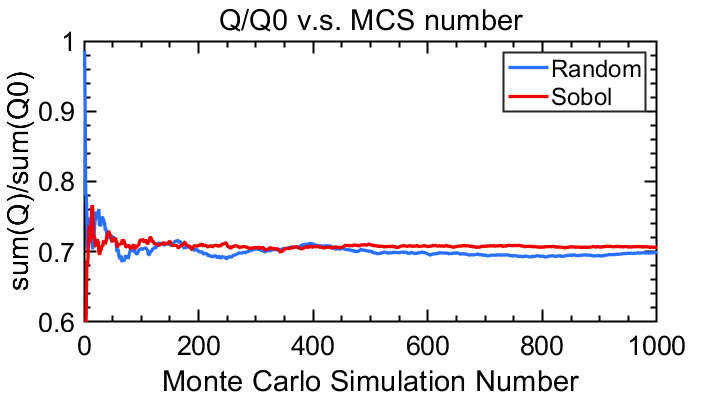


MC_NUM = data_s.MC_NUM;
X = 1:MC_NUM;
figure(1)
Q_mean_r = cumsum(data_r.SSI_Q)./(1:MC_NUM);
Q_mean_s = cumsum(data_s.SSI_Q)./(1:MC_NUM);
p1 = Plot(X,Q_mean_r,X,Q_mean_s);
p1.XLabel = 'Monte Carlo Simulation Number';
p1.YLabel = 'sum(Q)/sum(Q0)';
p1.Title = 'Q/Q0 v.s. MCS number';
p1.Legend = {'Random','Sobol'};
p1.LegendBox = 'on';

xlim([0 1000])
ylim([0.600 1.000])

% p1.LegendLoc
% p1.export('demand.png');
p1.delete;

#### （2）平均节点压力

平均节点压力$H(K_{number})$按照式（2）计算，

$H(K_{number})={\frac{\sum_{k=1}^{K_{number}}\sum_{i=1}^NH_i}{K_{number}}}$                                                                                                (2)

式中，$K_{number}$为MC模拟次数，$H(K_{number})$为前$K_{number}$次MC模拟的管网平均压力的均值，$H_i$节点$i$的压力。其中$H_{random}(1000)=0.41$，$H_{sobol}(1000)=0.36$，相对误差为$error=\frac{H_{random}(1000)-H_{sobol}(1000)}{H_{sobol}}=13.07\%$。

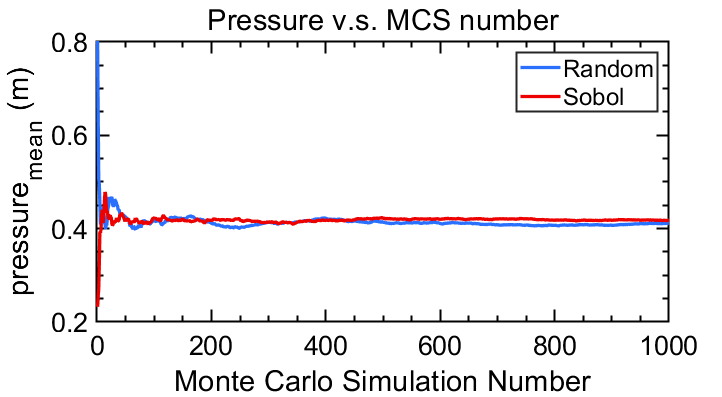

figure(2)
H_mean_r = cumsum(data_r.SSI_H)./(1:MC_NUM);
H_mean_s = cumsum(data_s.SSI_H)./(1:MC_NUM);
p2 = Plot(X,H_mean_r,X,H_mean_s);
p2.XLabel = 'Monte Carlo Simulation Number';
p2.YLabel = 'pressure_m_e_a_n (m)';
p2.Title = 'Pressure v.s. MCS number';
p2.Legend = {'Random','Sobol'};
p2.LegendBox = 'on';

% p2.export('pressure.png');
p2.delete;

#### （3）流量SSI均值的变异系数

根据中心极限定理，SSI的均值$SSI_{mean]$服从正态分布$N(\mu,\sigma/\sqrt{n})$，均值的变异系数$\beta$按照下式计算：

$\beta = \frac{1}{\sqrt{n}} \frac{\sqrt{VAR(SSI)}}{SSI_{mean}}$(3)

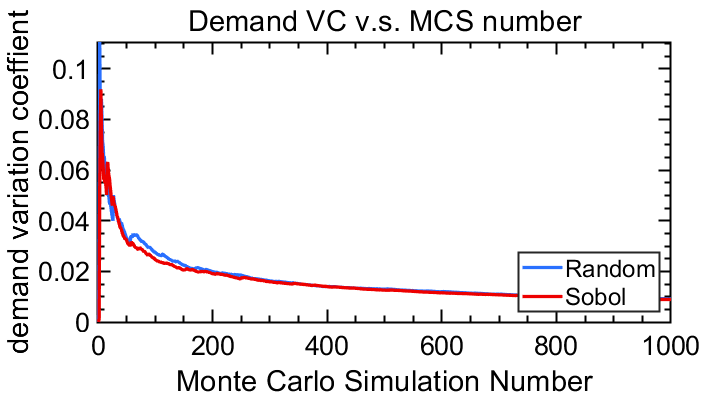

figure(3)
Q_sd_r = sqrt(cumsum((data_r.SSI_Q-Q_mean_r).^2)./(1:MC_NUM));
Q_vc_r = Q_sd_r./Q_mean_r;
Q_sd_s = sqrt(cumsum((data_s.SSI_Q-Q_mean_s).^2)./(1:MC_NUM));
Q_vc_s = Q_sd_s./Q_mean_s;
Q_mean_vc_r = Q_vc_r./(1:MC_NUM).^0.5;%均值的变异系数(HOU 博士论文第3章)
Q_mean_vc_s = Q_vc_s./(1:MC_NUM).^0.5;

p3 = Plot(X,Q_mean_vc_r,X,Q_mean_vc_s);
p3.XLabel = 'Monte Carlo Simulation Number';
p3.YLabel = 'demand variation coeffient';
p3.Title = 'Demand VC v.s. MCS number';
p3.Legend = {'Random','Sobol'};
p3.LegendBox = 'on';
p3.LegendLoc = 'southeast';

% p3.export('demand_vc.png');
p3.delete;

#### (4) 节点平均压力平均值H的变异系数

根据中心极限定理，SSI的均值$SSI_{mean]$服从正态分布$N(\mu,\sigma/\sqrt{n})$，均值的变异系数$\beta$按照下式计算：

$\beta = \frac{1}{\sqrt{n}} \frac{\sqrt{VAR(H)}}{H_{mean}}$(4)

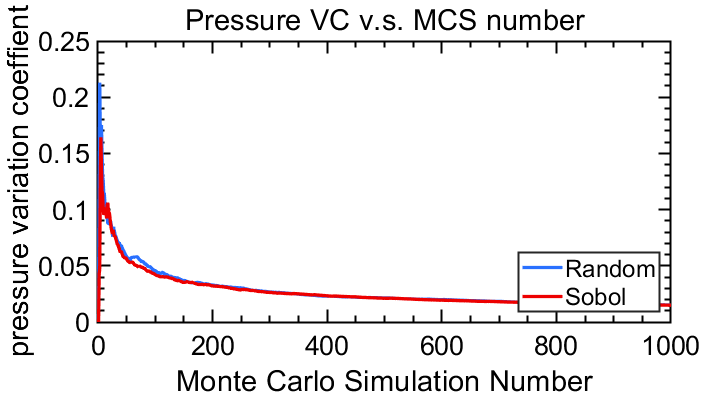

figure(4);
H_sd_r = sqrt(cumsum((data_r.SSI_H-H_mean_r).^2)./(1:MC_NUM));
H_vc_r = H_sd_r./H_mean_r;
H_sd_s = sqrt(cumsum((data_s.SSI_H-H_mean_s).^2)./(1:MC_NUM));
H_vc_s = H_sd_s./H_mean_s;
H_mean_vc_r = H_vc_r./(1:MC_NUM).^0.5;%均值的变异系数(HOU 博士论文第3章)
H_mean_vc_s = H_vc_s./(1:MC_NUM).^0.5;
p4 = Plot(X,H_mean_vc_r,X,H_mean_vc_s);
p4.XLabel = 'Monte Carlo Simulation Number';
p4.YLabel = 'pressure variation coeffient';
p4.Title = 'Pressure VC v.s. MCS number';
p4.Legend = {'Random','Sobol'};
p4.LegendBox = 'on';
p4.LegendLoc = 'southeast';

% p4.export('pressure_vc.png');
p4.delete;

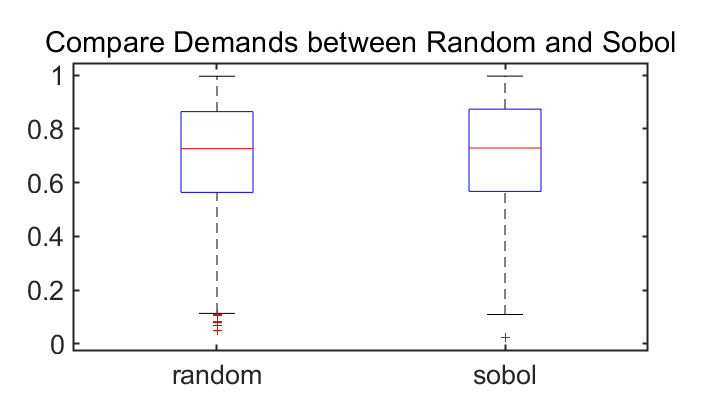


f5 = figure(5);
bpt1 = boxplot([data_r.SSI_Q',data_s.SSI_Q'],'Labels',{'random','sobol'},"Widths",0.25);
f5.CurrentAxes.Box = 'on';
f5.CurrentAxes.LineWidth = 1.5;
f5.CurrentAxes.Title.String = 'Compare Demands between Random and Sobol';
f5.CurrentAxes.FontSize = 20;
f5.CurrentAxes.FontName = 'Arial';
% f5.CurrentAxes.Units = 'inches';
pos = f5.CurrentAxes.Position;
height = 3;width = 6;
f5.CurrentAxes.Position = [pos(1),pos(2),width,height];

f5.DeleteFcn;

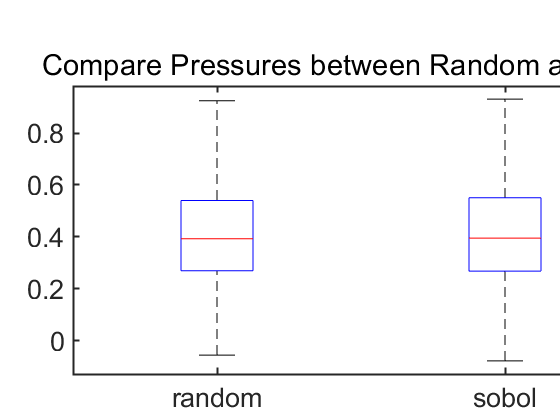

f6 = figure(6);
f = f6;
bpt2 = boxplot([data_r.SSI_H',data_s.SSI_H'],'Labels',{'random','sobol'},"Widths",0.25);
f.CurrentAxes.Box = 'on';
f.CurrentAxes.LineWidth = 1.5;
f.CurrentAxes.Title.String = 'Compare Pressures between Random and Sobol';
f.CurrentAxes.FontSize = 20;
f.CurrentAxes.FontName = 'Arial';
f.CurrentAxes.Units = 'inches';
pos = f.CurrentAxes.Position;
height = 3;width = 6;
f.CurrentAxes.Position = [pos(1),pos(2),width,height];

f.DeleteFcn;

f7 = figure(7);
f = f7;
axe1 = subplot(2,1,1);
ph1 = histogram(data_r.SSI_Q);
ph1.BinLimits = [0,1];
ph1.NumBins = 20;
ph1.FaceColor = [0.16,0.44,1.00];
axe1.Title.String = 'sum(Q)/sum(Q0) Distribution';
axe1.FontName = 'Arial';
axe1.FontSize = 20;
% axe1.XLabel.String = 'sum(Q)/sum(Q0)';
axe1.YLabel.String = 'counts';
% axe1.Title.String = 'random';
% axe1.Title.Position =  [0.1,90,0]
axe1.XTickLabel = '';
len1 = legend('random');
len1.Position = [0.15,0.58,0.16,0.05];
axe2 = subplot(2,1,2);
ph2 = histogram(data_s.SSI_Q);
ph2.BinLimits = [0,1];
ph2.NumBins = 20;
ph2.FaceColor = [0.93,0,0];
axe2.FontName = 'Arial';
axe2.FontSize = 20;
axe2.XLabel.String= 'sum(Q)/sum(Q0)';
axe2.YLabel.String = 'counts';
% axe2.Title.String = 'sobol';
% axe2.Title.Position =  [0.1,90,0]
len2 = legend('sobol');
len2.Position = [0.15,0.28,0.16,0.05];
pos = axe2.Position;
axe1.Position = [pos(1),pos(2)+pos(4),pos(3),pos(4)];
axe1.YAxis.Limits = axe2.YLim;
f.DeleteFcn;


f8 = figure(8);
f = f8;
axe1 = subplot(2,1,1);
ph1 = histogram(data_r.SSI_H);
ph1.BinLimits = [0,1];
ph1.NumBins = 20;
ph1.FaceColor = [0.16,0.44,1.00];
axe1.Title.String = 'Pressure Distribution';
axe1.FontName = 'Arial';
axe1.FontSize = 20;
% axe1.YAxis.Limits = [0,200];
% axe1.XLabel.String = 'sum(Q)/sum(Q0)';
axe1.YLabel.String = 'counts';
% axe1.Title.String = 'random';
% axe1.Title.Position =  [0.1,90,0]
axe1.XTickLabel = '';
len1 = legend('random');
len1.Position = [0.70,0.58,0.16,0.05];
axe2 = subplot(2,1,2);
ph2 = histogram(data_s.SSI_H);
ph2.BinLimits = [0,1];
ph2.NumBins = 20;
ph2.FaceColor = [0.93,0,0];
axe2.FontName = 'Arial';
axe2.FontSize = 20;
axe2.XLabel.String= 'Pressure (m)';
axe2.YLabel.String = 'counts';
% axe2.Title.String = 'sobol';
% axe2.Title.Position =  [0.1,90,0]
len2 = legend('sobol');
len2.Position = [0.70,0.28,0.16,0.05];
pos = axe2.Position;
axe1.Position = [pos(1),pos(2)+pos(4),pos(3),pos(4)];
axe1.YLim = axe2.YLim;
f.DeleteFcn;

## 3 结论

通过上述分析可以得到以下结论：

- Sobol 序列进行Monte Carlo模拟收敛速度比random伪随机序列快，模拟收敛所需的模拟次数少。

- Sobol 

- Sobol 序列的模拟结果更加集中，离散性更小。

## 参考文献

[1] 侯本伟. 城市供水管网抗震能力分析及性能化设计方法研究[D]. 北京: 北京工业大学, 2014.

[2] Probability & statistics for engineers & scientists: MyStatLab update[M].  WALPOLE R E, MYERS R H, MYERS S L, et al. the Ninth edition version. Boston: Pearson,  2017.